clear;close all

% File names
nodf='hw44.nod.dat';
belf='hw44.bel.dat';
dndf='hw44.dnd.dat';

nod=load(nodf);
nod=nod(:,2:3); % All nodes
bel=load(belf); 
bel=bel(:,2:3) % Boundary element incidence list

bel =     49    50
    50    36
   348   327
   369   348
   391   369
   413   391
   413   415
   415   394
   453   435
   454   453


bnod=unique(bel(:)) % Boundary nodes

bnod =      1
     2
     4
     6
    10
    13
    19
    23
    26
    27


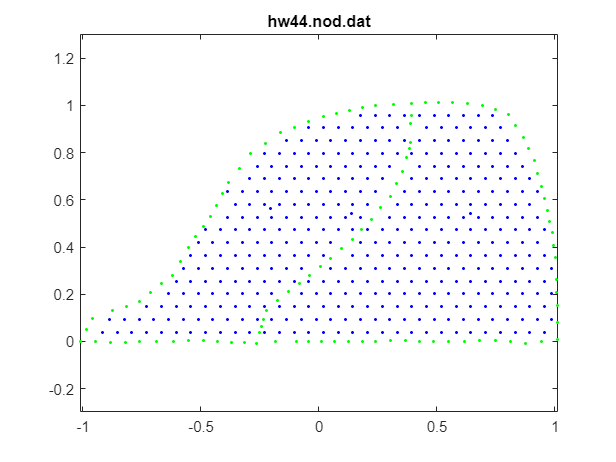

dnd=load(dndf); 
dnd=dnd(:,2); % Type 1 BC nodes (ground)

% Plot nodes
plot(nod(:,1),nod(:,2),'b.')
title(nodf)
axis equal

hold on
% Plot Boundary nodes
plot(nod(bnod,1),nod(bnod,2),'g.')

% Plot type 1 BC nodes
plot(nod(dnd,1),nod(dnd,2),'bo')

Index in position 1 is invalid. Array indices must be positive integers or logical values.

% Plot Current sink
plot(nod(492:493,1),nod(492:493,2),'ro')
% Plot Current source
plot(nod(503,1),nod(503,2),'gx','markersize',18,'linewidth',2)
legend('Nodes','Boundary Nodes','Dirichlet nodes','Boundary current sink','current source')

